# Trabajo grupal 2 (Métodos Numéricos)

- Sección: 5

- N° de grupo: 2

- Integrante 1 (líder):          

- Integrante 2:

- Integrante 3: Alejandra Brisa SIlva Salazar - 100%

- Integrante 4:

- Integrante 5:

**Observación:** No olvidar añadir el porcentaje de participación.

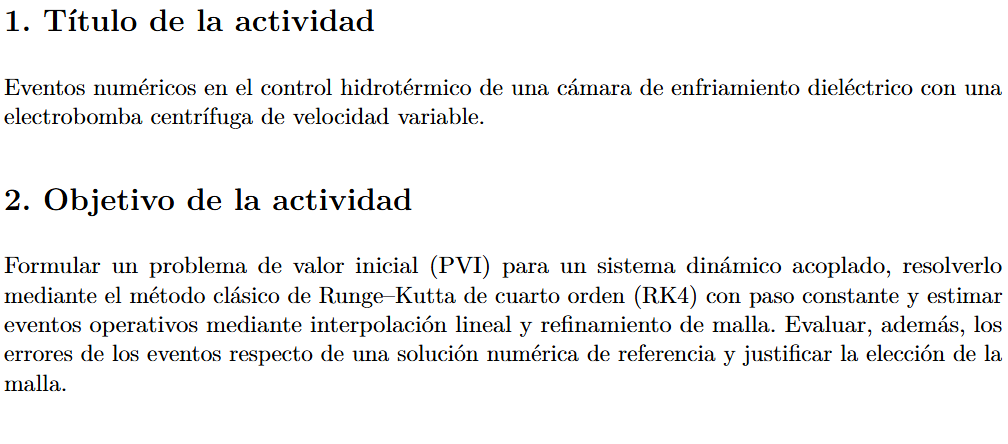

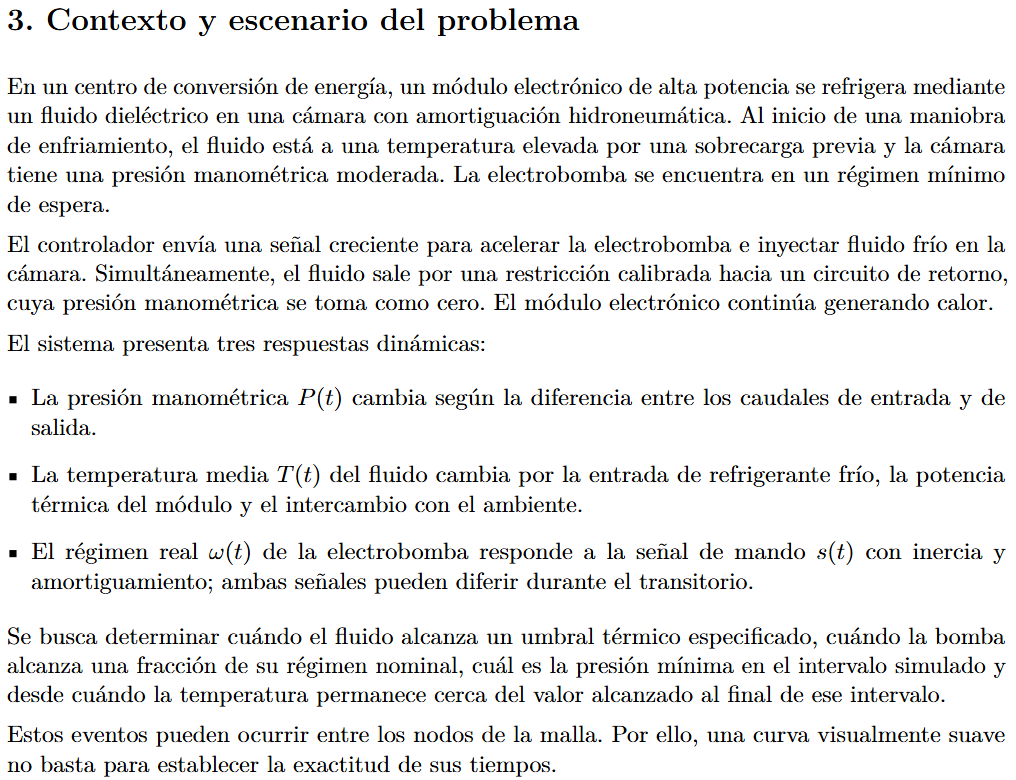

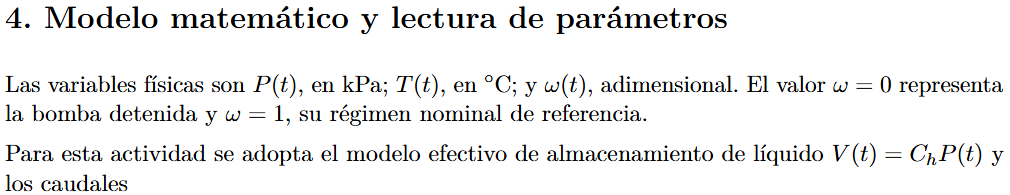

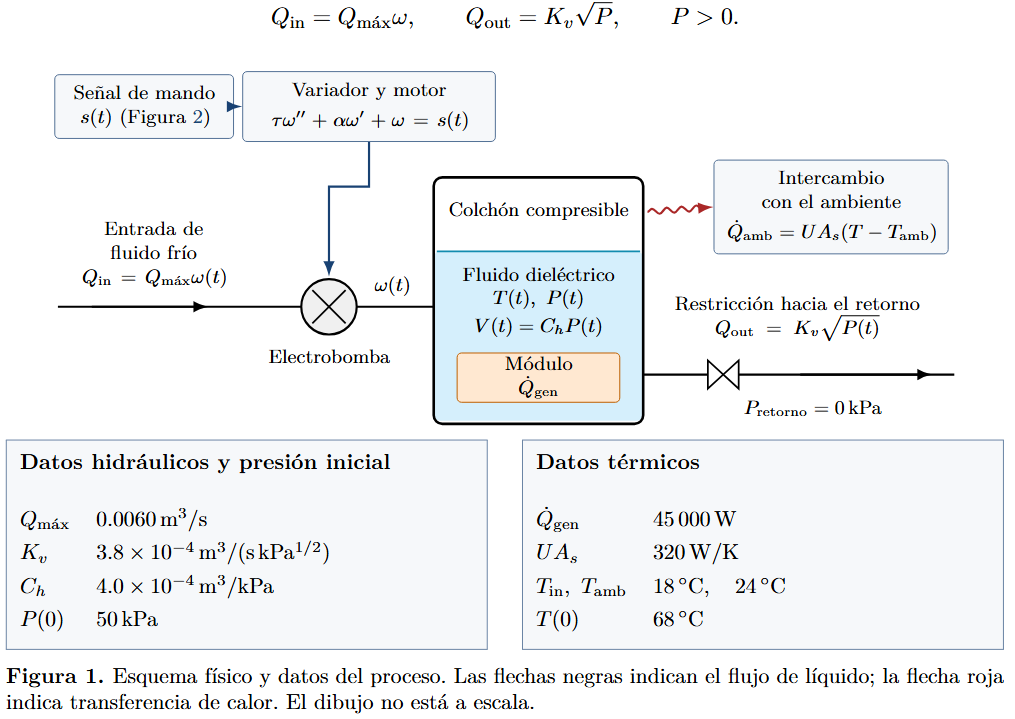

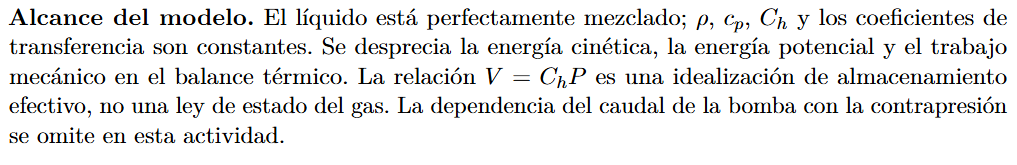

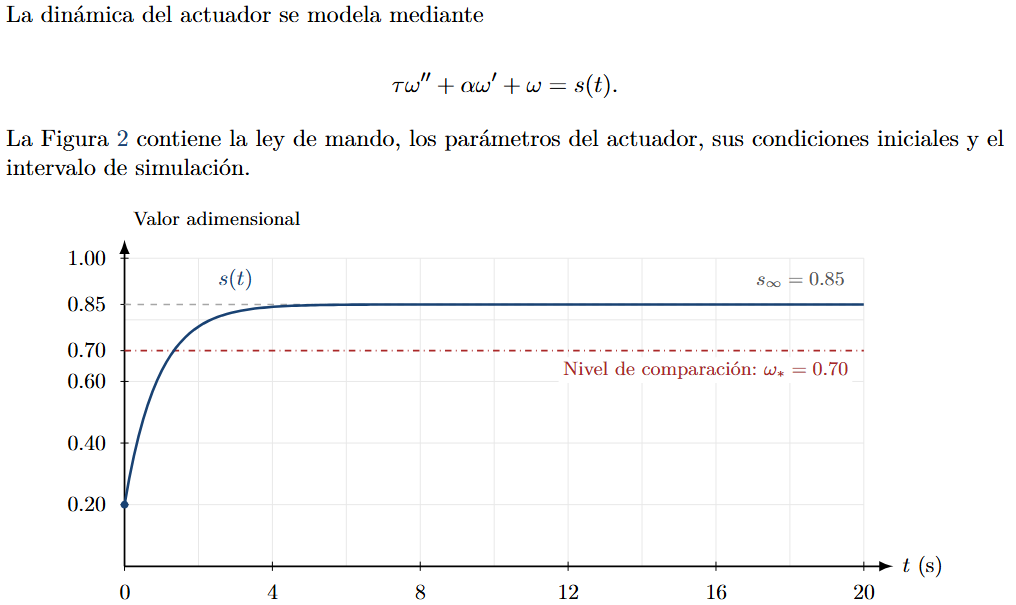

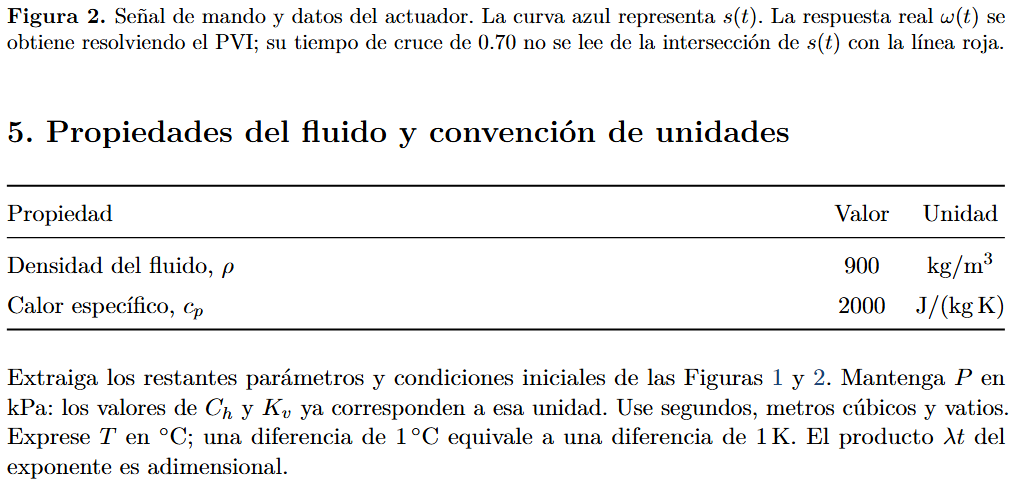

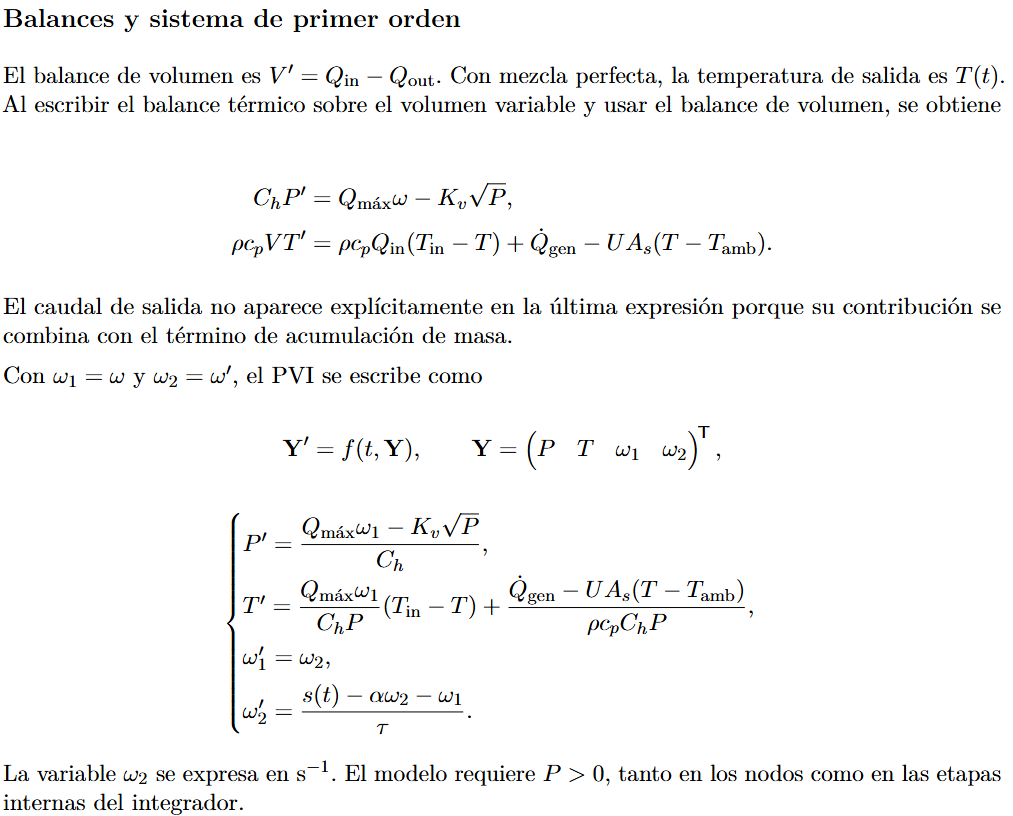

clearvars; clc; close all;

p.Qmax  = 0.0060;    
p.Kv    = 3.8e-4;   
p.Ch    = 4.0e-4;   
p.Qgen  = 45000;     
p.UAs   = 320;      
p.Tin   = 18;        
p.Tamb  = 24;        
p.rho   = 900;       
p.cp    = 2000;      
p.s0    = 0.20;      
p.ds    = 0.65;
p.lam   = 1.10;      
p.tau   = 0.80;     
p.alpha = 1.10;     

t0 = 0;  tf = 20;                 
Y0 = [50; 68; 0.20; 0];           
Ns = [50 100 200 400 800];        
DT = 0.5;                        
Tumbral = 42;  wumbral = 0.70;    

f = @(t,Y) edo_rc02(t,Y,p);
cV = p.rho*p.cp*p.Ch;             
fprintf('P''  = %.4f*w1 - %.4f*sqrt(P)\n', p.Qmax/p.Ch, p.Kv/p.Ch);

P'  = 15.0000*w1 - 0.9500*sqrt(P)


fprintf('T''  = [%.4f*w1*(%.0f - T) + %.4f - %.6f*(T - %.0f)]/P\n', ...
        p.Qmax/p.Ch, p.Tin, p.Qgen/cV, p.UAs/cV, p.Tamb);

T'  = [15.0000*w1*(18 - T) + 62.5000 - 0.444444*(T - 24)]/P


fprintf('w1'' = w2\n');

w1' = w2


fprintf('w2'' = %.4f*s(t) - %.4f*w2 - %.4f*w1\n', 1/p.tau, p.alpha/p.tau, 1/p.tau);

w2' = 1.2500*s(t) - 1.3750*w2 - 1.2500*w1


fprintf('s(t) = %.2f + %.2f*(1 - exp(-%.2f*t))\n', p.s0, p.ds, p.lam);

s(t) = 0.20 + 0.65*(1 - exp(-1.10*t))



disp('Y(0) = [P; T; w1; w2] ='); disp(Y0)

Y(0) = [P; T; w1; w2] =
   50.0000
   68.0000
    0.2000
         0



disp('f(0,Y(0)) ='); disp(f(0,Y0))

f(0,Y(0)) =
   -3.7175
   -2.1411
         0
         0



**1. Significado de los eventos**

tT42 corresponde al primer cruce descendente de 42 °C debido al ingreso de líquido frío, mientras que tω70 indica el primer cruce ascendente de ω = 0.70, considerando la inercia de la bomba mediante el PVI. Por su parte, tP,mín representa la presión mínima global en [t₀, t_f], que ocurre cuando se igualan los caudales (P′ = 0), y test,T indica desde cuándo la temperatura permanece dentro de ±0.5 K respecto a T(t_f), sin que esto implique necesariamente un equilibrio definitivo.

**2. Deducción de la fórmula para t*_lin**

Para encontrar el instante en que la variable alcanza el umbral y*, se iguala la interpolación lineal a dicho valor y luego se despeja el tiempo:

L(t) = y*

yᵢ + [(yᵢ₊₁ − yᵢ)/(tᵢ₊₁ − tᵢ)] · (t − tᵢ) = y*

t*_lin = tᵢ + [(y* − yᵢ)/(yᵢ₊₁ − yᵢ)] · (tᵢ₊₁ − tᵢ)

La condición (yᵢ − y*)(yᵢ₊₁ − y*) < 0 garantiza que los puntos están a lados opuestos del umbral, que yᵢ₊₁ ≠ yᵢ y que la fracción está entre 0 y 1; por eso, el cruce queda dentro del intervalo.

**3. Dirección del cruce y casos especiales**

El cruce es descendente cuando yᵢ > y* > yᵢ₊₁ y ascendente cuando yᵢ < y* < yᵢ₊₁, lo cual también se identifica observando si la diferencia yᵢ₊₁ − yᵢ es negativa o positiva. Si el umbral coincide con un nodo, este se asigna al intervalo que termina en él, usando intervalos semiabiertos, para evitar contarlo dos veces; además, se debe cumplir yᵢ₊₁ ≠ yᵢ para aplicar la fórmula. Si la variable solo toca el umbral sin atravesarlo, no existe un cruce, y si todo el segmento permanece sobre él, tampoco hay un instante único.

**4. Error del integrador frente al de interpolación**

Para una solución suficientemente suave, RK4 presenta un error global de orden O(h⁴), mientras que la interpolación lineal tiene un error de orden O(h²), incluso si los puntos son exactos. Por ello, en un cruce simple, donde y′(t*) ≠ 0, se espera que el error del tiempo de cruce sea O(h²), es decir, que al reducir h a la mitad disminuya aproximadamente cuatro veces. Esto también explica por qué una gráfica puede verse suave sin garantizar tiempos precisos: un pequeño error δy puede generar un cambio importante en el tiempo, según δt ≈ δy/|y′(t*)|, especialmente cuando la pendiente en el cruce es pequeña.

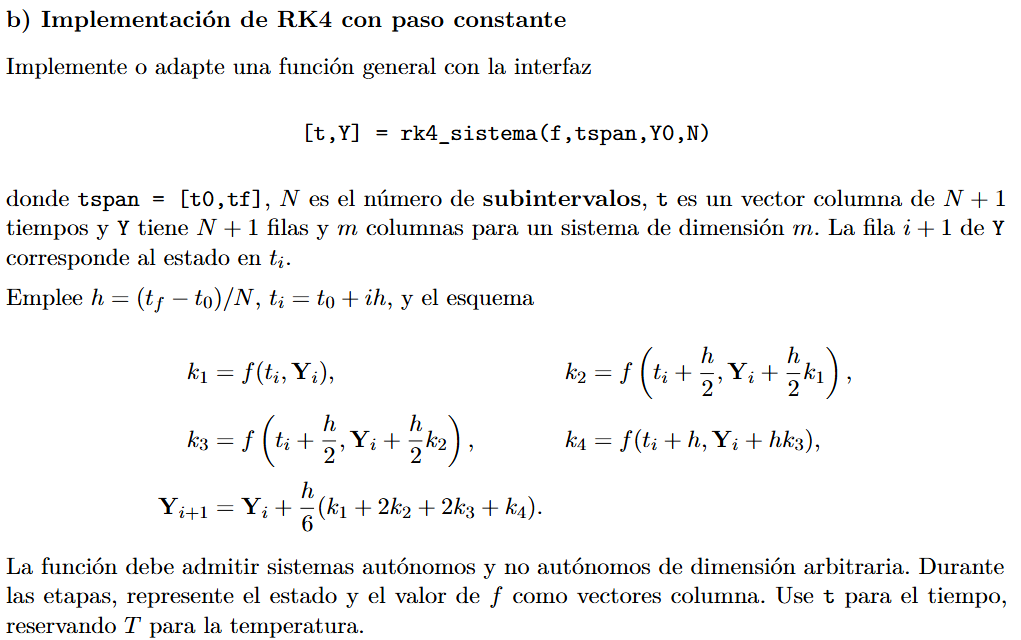

2. 

ans = 2

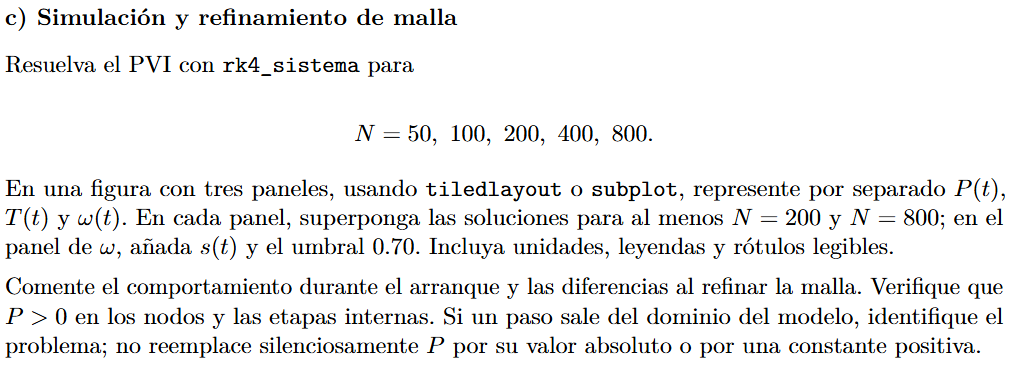

3.

ans = 3

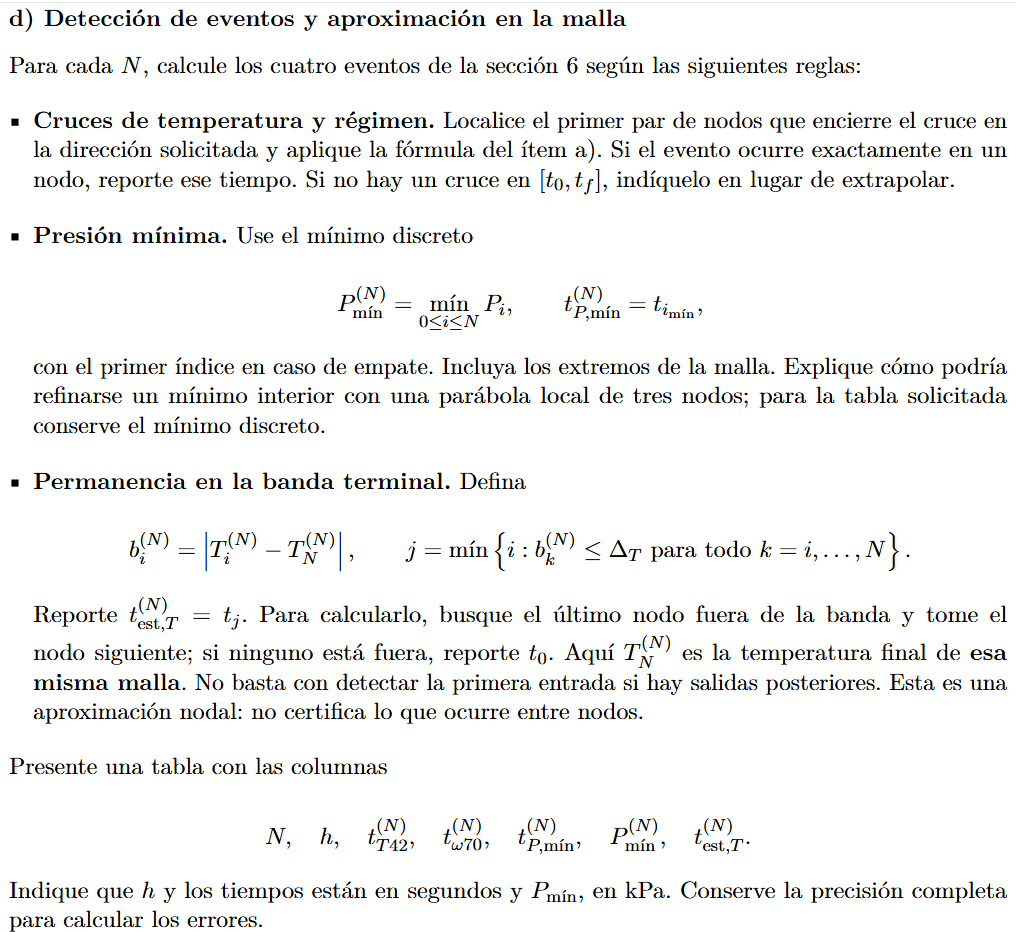

4.

ans = 4

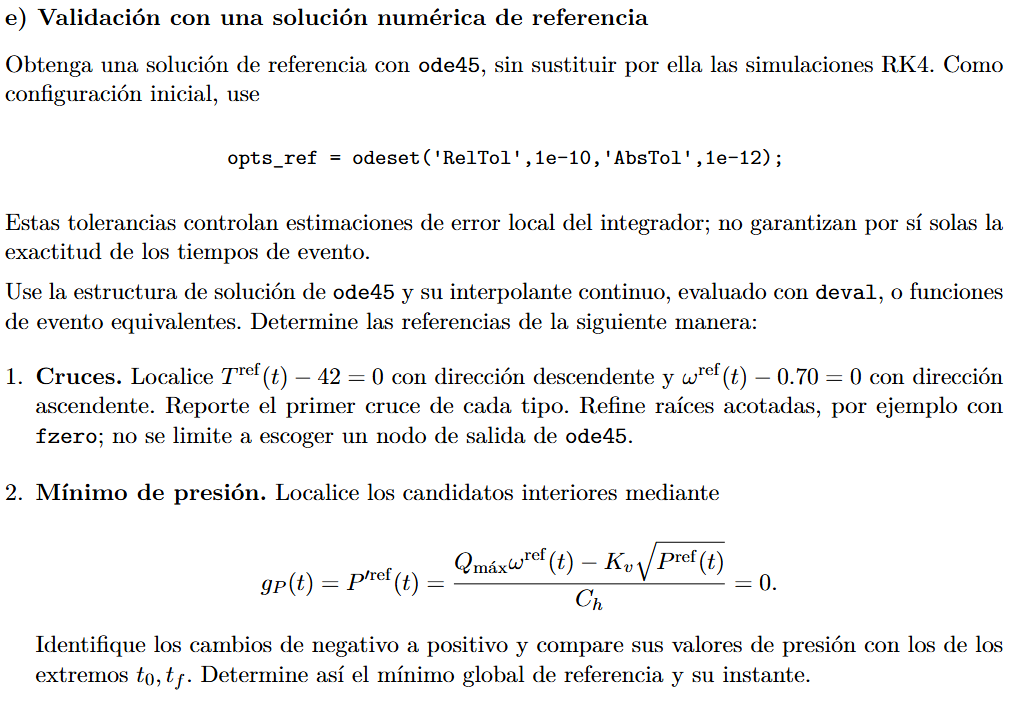

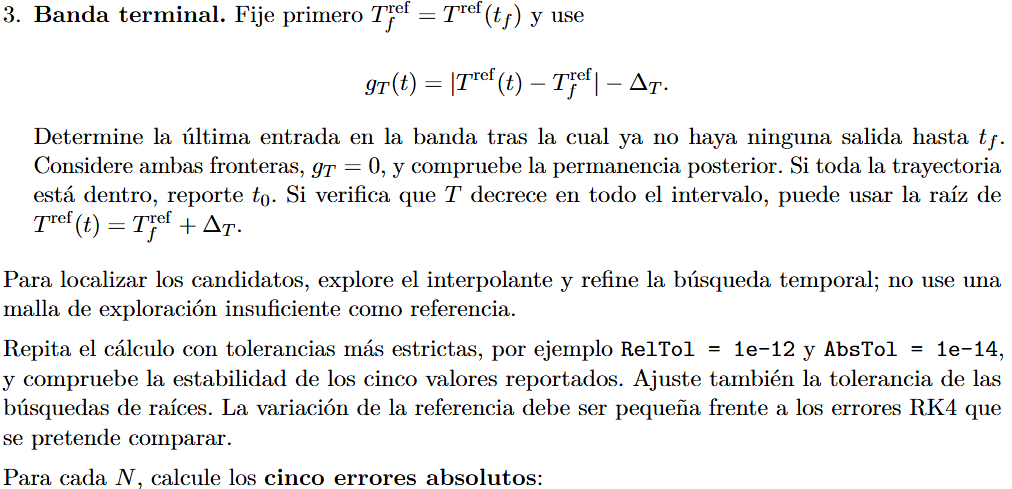

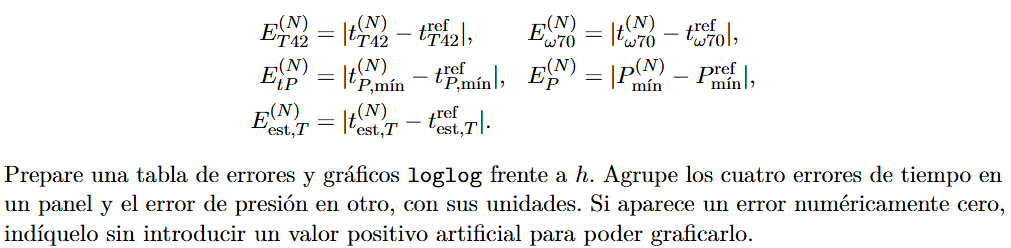

5.

ans = 5

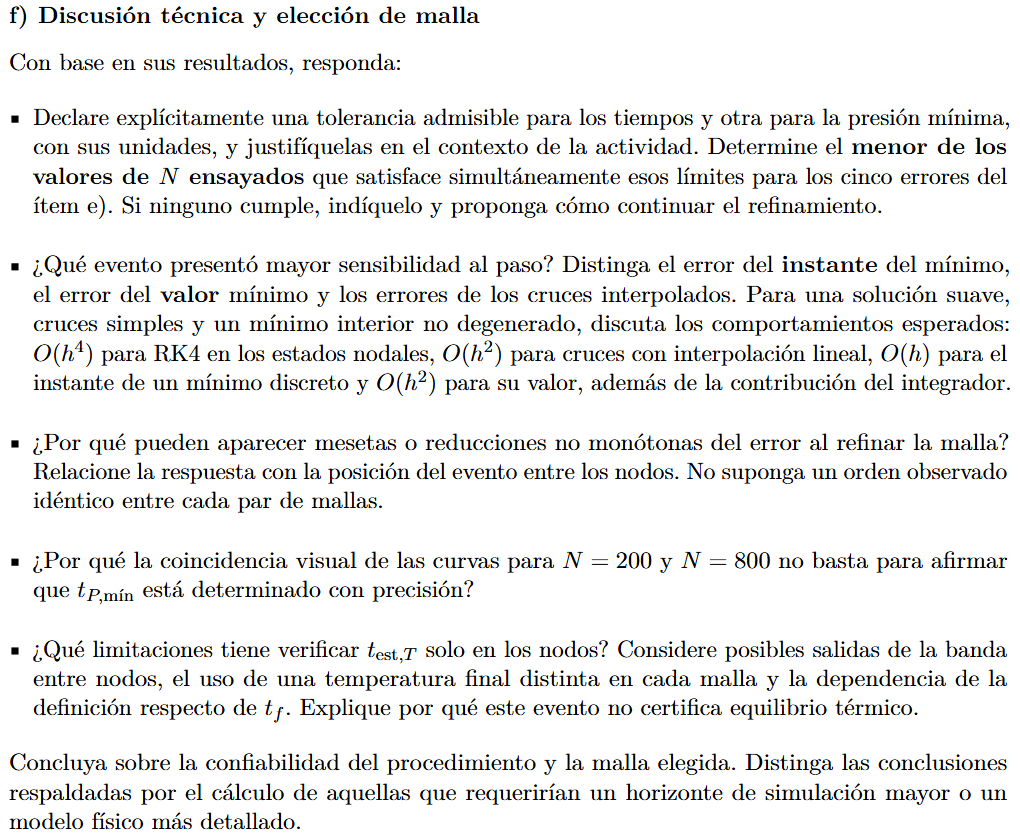

function [t,Y] = rk4_sistema(f,tspan,Y0,N)
if N < 1 || N ~= fix(N), error('N debe ser un entero positivo.'); end
t0 = tspan(1);  tf = tspan(2);
h  = (tf - t0)/N;
m  = numel(Y0);
t  = t0 + (0:N)'*h;
Y  = zeros(N+1,m);
Y(1,:) = Y0(:).';
for i = 1:N
    yi = Y(i,:).';                          
    k1 = f(t(i),       yi);                k1 = k1(:);
    k2 = f(t(i) + h/2, yi + h/2*k1);       k2 = k2(:);
    k3 = f(t(i) + h/2, yi + h/2*k2);       k3 = k3(:);
    k4 = f(t(i) + h,   yi + h*k3);         k4 = k4(:);
    Y(i+1,:) = (yi + h/6*(k1 + 2*k2 + 2*k3 + k4)).';
end
end

function dY = edo_rc02(t,Y,p)
P = Y(1);  T = Y(2);  w1 = Y(3);  w2 = Y(4);
if ~(P > 0)
    error('RC02:dominio','Fuera del dominio: P = %g kPa <= 0 en t = %.6f s.',P,t);
end
dP  = (p.Qmax*w1 - p.Kv*sqrt(P))/p.Ch;
dT  = p.Qmax*w1/(p.Ch*P)*(p.Tin - T) ...
    + (p.Qgen - p.UAs*(T - p.Tamb))/(p.rho*p.cp*p.Ch*P);
dw1 = w2;
dw2 = (s_mando(t,p) - p.alpha*w2 - w1)/p.tau;
dY  = [dP; dT; dw1; dw2];
end

function s = s_mando(t,p)
s = p.s0 + p.ds*(1 - exp(-p.lam*t));
end

function [tc,hay] = cruce_lineal(t,y,ystar,dir)
tc = NaN;  hay = false;
g = dir*(y - ystar);
for i = 1:numel(t)-1
    if g(i) < 0 && g(i+1) >= 0
        if g(i+1) == 0 && i+1 < numel(t) && g(i+2) < 0
            continue                             
        end
        tc  = t(i) + (ystar - y(i))/(y(i+1) - y(i))*(t(i+1) - t(i));
        hay = true;
        return
    end
end
end

function graficar_estados(Ns,tN,YN,p,sel,xl)

figure('Color','w','Position',[100 100 900 850]);
tl = tiledlayout(3,1,'TileSpacing','compact','Padding','compact');
estilo = {':','--','-'};  ancho = [1.8 1.6 1.4];
etiq = {'P (kPa)','T (°C)','\omega (adim.)'};
tit  = {'Presión manométrica','Temperatura del fluido','Régimen de la bomba'};
for v = 1:3
    nexttile; hold on; grid on; box on
    for q = 1:numel(sel)
        k = sel(q);
        plot(tN{k},YN{k}(:,v),estilo{q},'LineWidth',ancho(q), ...
             'DisplayName',sprintf('RK4, N = %d',Ns(k)));
    end
    if v == 2
        yline(42,'k:','DisplayName','T = 42 °C');
    end
    if v == 3
        tt = linspace(xl(1),xl(2),2000);
        plot(tt,s_mando(tt,p),'-.','LineWidth',1.3,'DisplayName','s(t)');
        yline(0.70,'r--','LineWidth',1.2,'DisplayName','\omega^* = 0.70');
        xlabel('t (s)');
    end
    ylabel(etiq{v}); title(tit{v}); xlim(xl); legend('Location','best');
end
title(tl,'Soluciones RK4 del sistema hidrotérmico');
end